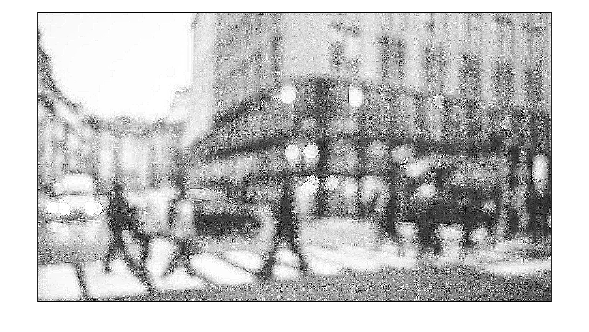

im = im2gray(imread("razm.jpg")); %исходный массив 
yadro = [0 -1 0; -1 5 -1; 0 -1 0];
ans1 = cast(conv2(im,yadro),"uint8");
ans1 = cast(conv2(ans1,yadro),"uint8");

ans2 = cast(svert(im,yadro),"uint8");
ans2 = cast(svert(ans2,yadro),"uint8");

imshow(ans1)

imshow(ans2)


% imwrite(im,'C:\LATEX\Fourier_analiz\Fourier_6\3_0.png');
imwrite(ans1,'C:\LATEX\Fourier_analiz\Fourier_6\3_conv.png');
imwrite(ans2,'C:\LATEX\Fourier_analiz\Fourier_6\3_four.png');

function y = svert(im,m) %передается ядро
    h = height(im); w = width(im); %высота и ширина исходного
    f_im = fftshift(fft2(im, h+height(m)-1,w+width(m)-1)); %образ Фурье для изображения
    f_m = fftshift(fft2(m, h+height(m)-1,w+width(m)-1)); %образ для ядра
    d = f_im.*f_m;
    y = ifft2(ifftshift(d));
end